Extrapolate Equations From True Servo Rotation

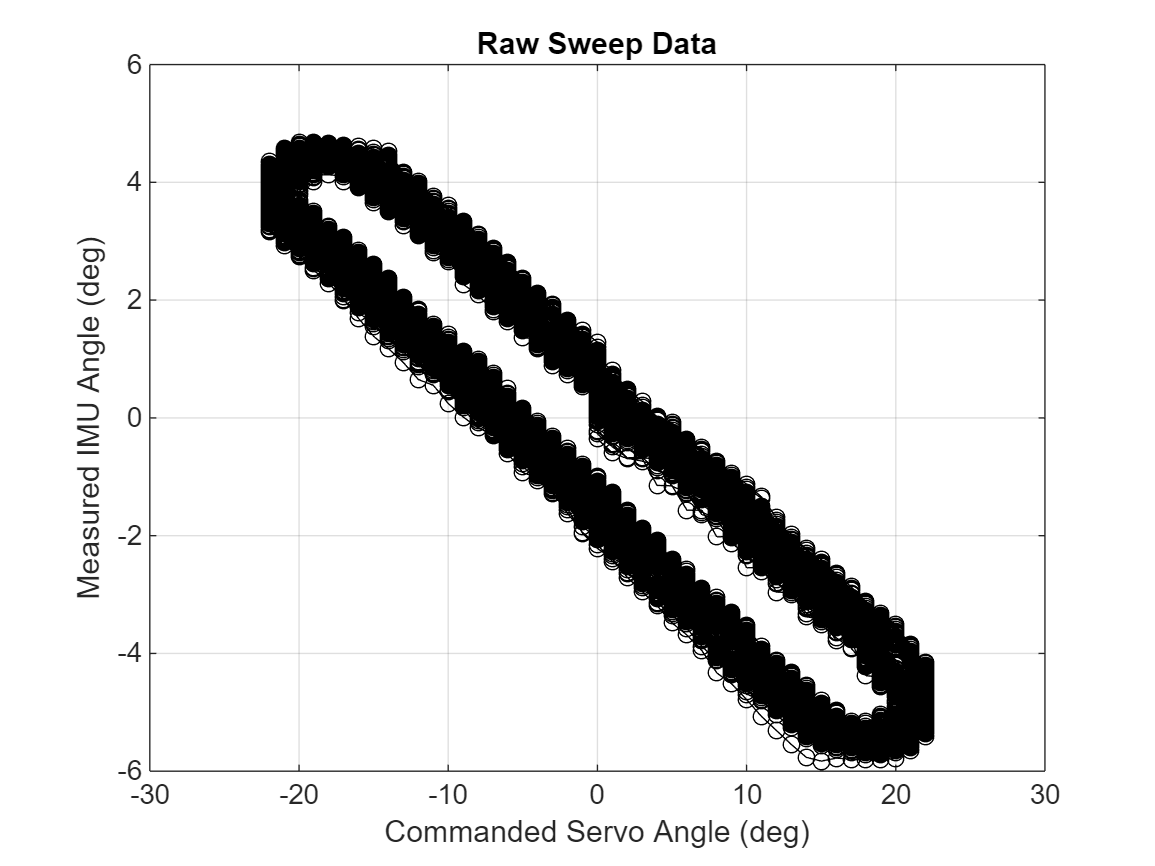

filename1 = 'data/YAW1.TXT'; 
filename2 = 'data/YAW2.TXT';
filename3 = 'data/YAW3.TXT';
filename4 = 'data/YAW4.TXT';
filename5 = 'data/YAW5.TXT';

%data1 = readmatrix(filename1);
data2 = readmatrix(filename2);
data3 = readmatrix(filename3);
data4 = readmatrix(filename4);
data5 = readmatrix(filename5);

data = [data2; data3; data4; data5];

servo = data(:,1);            % Commanded servo angle
gimbal = data(:,2);           % Actual gimbal angle from IMU

figure;
plot(servo, gimbal, 'ko-');
xlabel('Commanded Servo Angle (deg)');
ylabel('Measured IMU Angle (deg)');
title('Raw Sweep Data');
grid on;

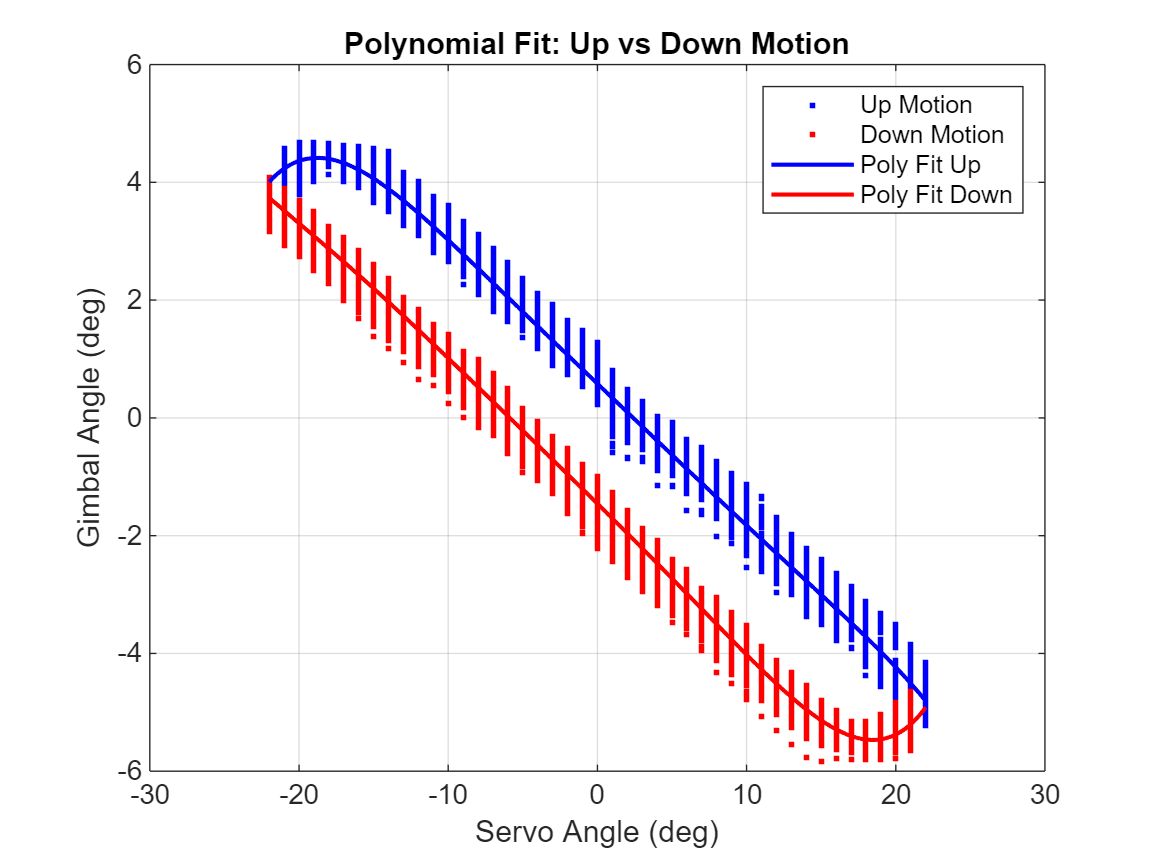


% Separating positive motion from negative motion
direction = sign(diff(servo));
up_idx = find([0; direction] > 0);   
down_idx = find([0; direction] < 0);  

servo_up = servo(up_idx);
gimbal_up = gimbal(up_idx);

servo_down = servo(down_idx);
gimbal_down = gimbal(down_idx);

%Fit the data with polynomials
order = 6;
p_up = polyfit(servo_up, gimbal_up, order);
p_down = polyfit(servo_down, gimbal_down, order);

servo_range = linspace(min(servo), max(servo), 500);
gimbal_fit_up = polyval(p_up, servo_range);
gimbal_fit_down = polyval(p_down, servo_range);

%plot
figure;
plot(servo_up, gimbal_up, 'b.', 'DisplayName', 'Up Motion');
hold on;
plot(servo_down, gimbal_down, 'r.', 'DisplayName', 'Down Motion');
plot(servo_range, gimbal_fit_up, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Poly Fit Up');
plot(servo_range, gimbal_fit_down, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Poly Fit Down');
xlabel('Servo Angle (deg)');
ylabel('Gimbal Angle (deg)');
title('Polynomial Fit: Up vs Down Motion');
legend;
grid on;


%coefficients for the polynomials
fprintf('Polynomial Coefficients (Up Motion):\n');

Polynomial Coefficients (Up Motion):


fprintf('%.15f\n', p_up);

-0.000000010287811
0.000000216036084
0.000000343473319
-0.000016893435150
0.000217421300334
-0.242767521833985
0.581279061853726



fprintf('\nPolynomial Coefficients (Down Motion):\n');


Polynomial Coefficients (Down Motion):


fprintf('%.15f\n', p_down);

0.000000009738129
0.000000329672653
0.000000239962733
-0.000049198072653
-0.000602646843026
-0.250136380714918
-1.457193330894172
